# **Procesamiento de Imagenes Digitales**

# **Taller 7**

## Filtro pasa-bajo en el dominio frecuencial

Cargue la imagen 'TextGaps.tif', y visualicela en la `figura 1`.

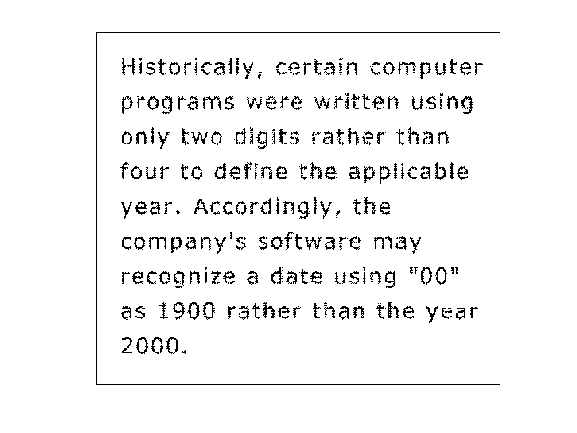

T = imread('TextGaps.tif');
figure(1);
imshow(T);

Aunque los humanos llenan los vacíos en los caracteres (`figura 1`) visualmente sin dificultad, los sistemas de reconocimiento basados en inteligencia artificial tienen dificultades reales para leer caracteres incompletos. Un posible solución para manejar este problema es reducir esos pequeños huecos en la imagen orignal difuminándola.

Aplique un filtro pasa-bajo Gaussiano en el dominio frecuencial, con la frecuencia de corte igual al $10\%$ del numero de columnas de la imagen,compare la imagen original con la filtrada en sub plot horizontal en la `figura 2`.

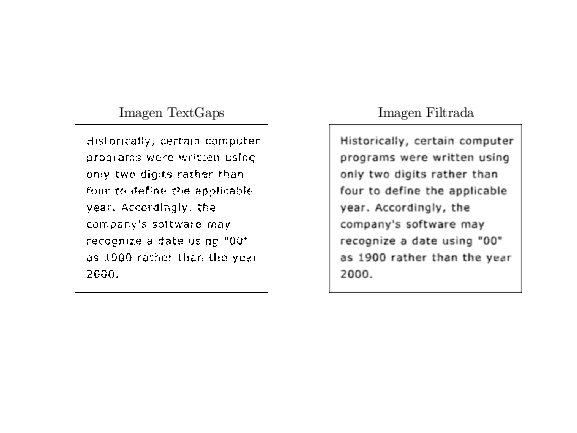

PQ = 2*size(T);
u = 0:(PQ(1)-1);
v = 0:(PQ(2)-1);
idx = find(u>PQ(1)/2);
u(idx) = u(idx)-PQ(1);
idy = find(v>PQ(2)/2);
v(idy) = v(idy)-PQ(2);
[V,U] = meshgrid(v,u);
D = hypot(U,V);
Do = 0.1*PQ(2);
H = exp(-(D.^2)/(2*(Do^2)));
F = fft2(T,size(H,1),size(H,2));
g = ifft2(H.*F);
g = g(1:size(T,1),1:size(T,2));
g = im2uint8(mat2gray(g));
figure(2);
subplot(1,2,1);imshow(T);title('Imagen TextGaps','Interpreter','Latex');
subplot(1,2,2);imshow(g);title('Imagen Filtrada','Interpreter','Latex');

Finalice con su comentario: en el ejercicio se plantea una solución que consiste en difunar la imagen para que se pueda distinguir las letras, la imagen se trato con el filtro paso bajo gaussiano que al igual que un filtro de media difumina la imagen y le da un efecto blured, pero en consecuencia hace que se pierda nitidez.

## Filtro pasa-alto ideal en el dominio frecuencial

Cargue la imagen 'characters.tif', y visualicela en la `figura 3`.

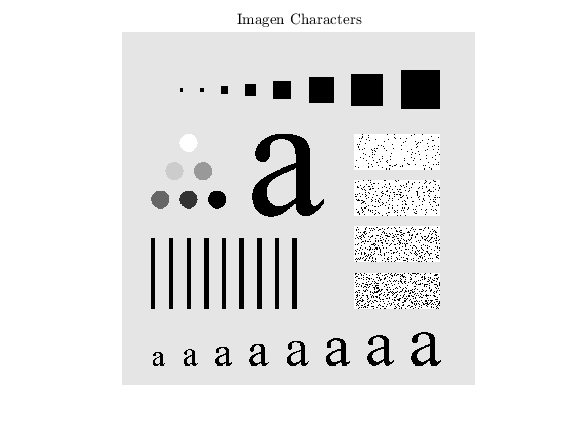

C = imread('characters.tif');
figure(3);
imshow(C);title('Imagen Characters','Interpreter','Latex');

Aplique un filtro pasa-alto ideal con frecuencia de corte igual a 30, 60 y 160. Visualice como imagen en un subplot horizontal en la `figura 4`.

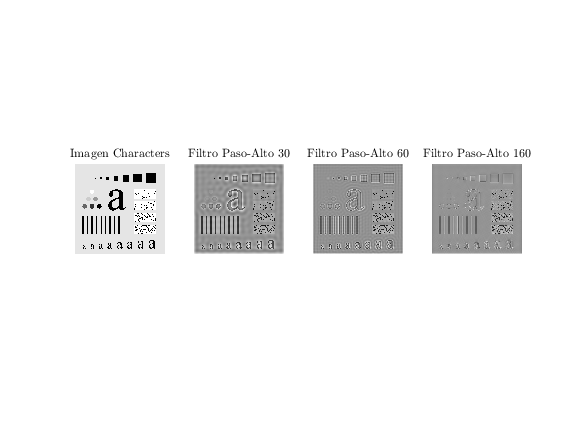

PQ = 2*size(C);
u = 0:(PQ(1)-1);
v = 0:(PQ(2)-1);
idx = find(u>PQ(1)/2);
u(idx) = u(idx)-PQ(1);
idy = find(v>PQ(2)/2);
v(idy) = v(idy)-PQ(2);
[V,U] = meshgrid(v,u);
D = hypot(U,V);
MN = size(D);
D30 = find(D<30);
D60 = find(D<60);
D160 = find(D<160);
Do_30 = ones(MN(1),MN(2));
Do_60 = ones(MN(1),MN(2));
Do_160 = ones(MN(1),MN(2));
Do_30(D30) = 0;
Do_60(D60) = 0;
Do_160(D160) = 0;

F1 = fft2(C,size(Do_30,1),size(Do_30,2));
F2 = fft2(C,size(Do_60,1),size(Do_60,2));
F3 = fft2(C,size(Do_160,1),size(Do_160,2));

j = ifft2(Do_30.*F1);
j = j(1:size(C,1),1:size(C,2));
j = im2uint8(mat2gray(j));

k = ifft2(Do_60.*F2);
k = k(1:size(C,1),1:size(C,2));
k = im2uint8(mat2gray(k));

l = ifft2(Do_160.*F3);
l = l(1:size(C,1),1:size(C,2));
l = im2uint8(mat2gray(l));

figure(4);
subplot(1,4,1);imshow(C);title('Imagen Characters','Interpreter','Latex');
subplot(1,4,2);imshow(j);title('Filtro Paso-Alto 30','Interpreter','Latex');
subplot(1,4,3);imshow(k);title('Filtro Paso-Alto 60','Interpreter','Latex');
subplot(1,4,4);imshow(l);title('Filtro Paso-Alto 160','Interpreter','Latex');

Finalice con su comentario: el filtro de corte de frecuencia se usa ya sea para permitir el paso de frecuencias que se encuentren por encima o por debajo de la frecuencia de filtro, en este caso se uso un filtro paso alto que permite el paso de las frecuencias que se encuentra solo por encima, en consecuencia se tiene un filtro abrupto en el paso de las frecuencias ocasionando un efecto de anillos en la imagen, a medida que el filtro se extiende se reduce mas el paso de las frecuencias por lo que se hace mas dificil diferenciar la forma de la imagen.

## Filtro pasa-alto en el dominio frecuencial

Cargue la imagen 'Thumb.tif', aplique un filtro pasa-alto Gaussiano en el dominio frecuencial, con el $5\%$ del padding vertical como frecuencia de corte. Visualice en un subplot horizontal, la imagen original y la filtrada, en la `figura 5`. 

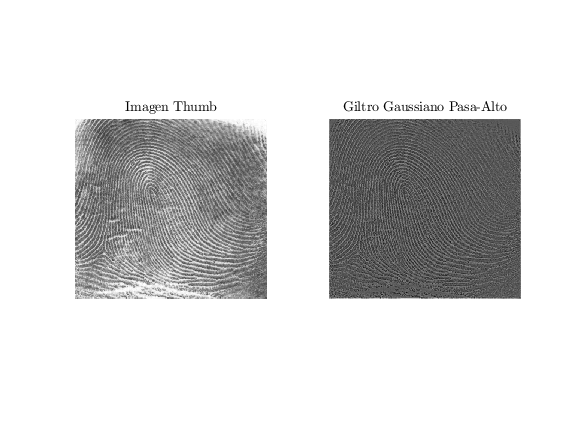

Th = imread('Thumb.tif');
PQ = 2*size(Th);
u = 0:(PQ(1)-1);
v = 0:(PQ(2)-1);
idx = find(u>PQ(1)/2);
u(idx) = u(idx)-PQ(1);
idy = find(v>PQ(2)/2);
v(idy) = v(idy)-PQ(2);
[V,U] = meshgrid(v,u);
D = hypot(U,V);
Do = 0.05*PQ(2);
H = 1-exp(-(D.^2)/(2*(Do^2)));
F = fft2(Th,size(H,1),size(H,2));
g = ifft2(H.*F);
g = g(1:size(Th,1),1:size(Th,2));
g = im2uint8(mat2gray(g));
figure(5);
subplot(1,2,1);imshow(Th);title('Imagen Thumb','Interpreter','Latex');
subplot(1,2,2);imshow(g);title('Giltro Gaussiano Pasa-Alto','Interpreter','Latex');

Finalice con su comentario: con el filtro paso alto gaussiano podemos resaltar la forma de la imagen por lo que se puede distingie mejor el relieve de la huella ademas que por ser un filtro que suavisa el paso de las frecuencias en cierta medida, no se ocaciona el efecto de anillos que se produce con un filtro paso-alto ideal, por ello se puede distinguir mejor la huella.

## Énfasis en el filtrado de altas frecuencias

Cargue la imagen 'chest.tif', aplique un filtro pasa-alto Butterworth de orden 2, en el dominio frecuencial, con el $5\%$ del padding vertical como frecuencia de corte. Visualice en un subplot horizontal, la imagen original y la filtrada, en la `figura 6`. 

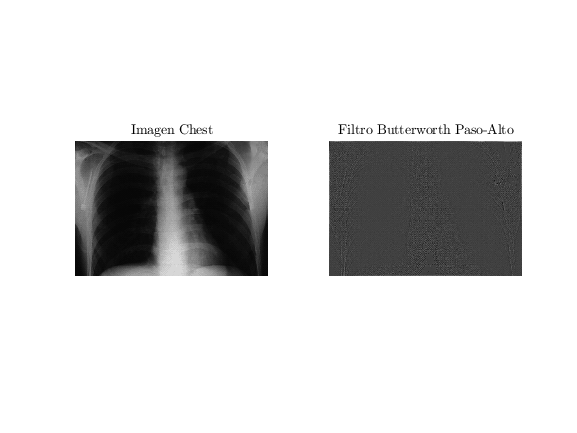

Ch = imread('chest.tif');
PQ = 2*size(Ch);
u = 0:(PQ(1)-1);
v = 0:(PQ(2)-1);
idx = find(u>PQ(1)/2);
u(idx) = u(idx)-PQ(1);
idy = find(v>PQ(2)/2);
v(idy) = v(idy)-PQ(2);
[V,U] = meshgrid(v,u);
D = hypot(U,V);
Do = 0.05*PQ(2);
H = (1./(1+(Do./D)).^4);
F = fft2(Ch,size(H,1),size(H,2));
g = ifft2(H.*F);
g = g(1:size(Ch,1),1:size(Ch,2));
g = im2uint8(mat2gray(g));
figure(6);
subplot(1,2,1);imshow(Ch);title('Imagen Chest','Interpreter','Latex');
subplot(1,2,2);imshow(g);title('Filtro Butterworth Paso-Alto','Interpreter','Latex');

La técnica* High-frequency emphasis* utilizada para mejorar el resultado en el filtrado de altas frecuencias, propone la siguiente función de transferencia: 

 
$$H_{hfe}(u,v) = a + bH_{HP}(u,v)$$


en donde $a$ es un valor de compensación, $b$ un factor amplificador y $H_{HP}(u,v)$ es la función de transferencia del filtro pasa-alto. Aplique la tecnica *High-frequency emphasis, *que utiliza la función de transferencia definida,  a la imagen origina y posteriormente aplique una tecnica para mejorar el contraste a la imagen resultante. Visualice en un subplot horizontal estas dos magenes resultantes en la figura 7.

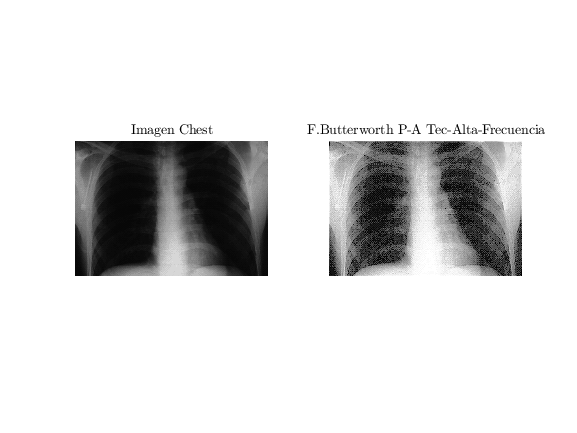

H2 = 0.5 + 2*H;
F = fft2(Ch,size(H2,1),size(H2,2));
g = ifft2(H2.*F);
g = g(1:size(Ch,1),1:size(Ch,2));
g = im2uint8(mat2gray(g));
g = histeq(g);
figure(7);
subplot(1,2,1);imshow(Ch);title('Imagen Chest','Interpreter','Latex');
subplot(1,2,2);imshow(g);title('F.Butterworth P-A Tec-Alta-Frecuencia','Interpreter','Latex');

Finalice con su comentario: el filtro de paso alto de Butterworth al igual que los demas filtro de paso alto busca resaltar la forma de la imagen pero al ser un filtro de Butterworth de orden 2 se pierde mucha información importante, por lo que si se le aplica el filtro con la tecnica de alta frecuencia que ayuda a resaltar las frecuencias, y dejar pasar mas con el valor de compensación y la equialización ayuda al contraste de la imagen y ayuda a detallarla mejor, obtenemos una imagen en donde se distingue su forma.